## Example 5.1

## Time response characteristics of the system

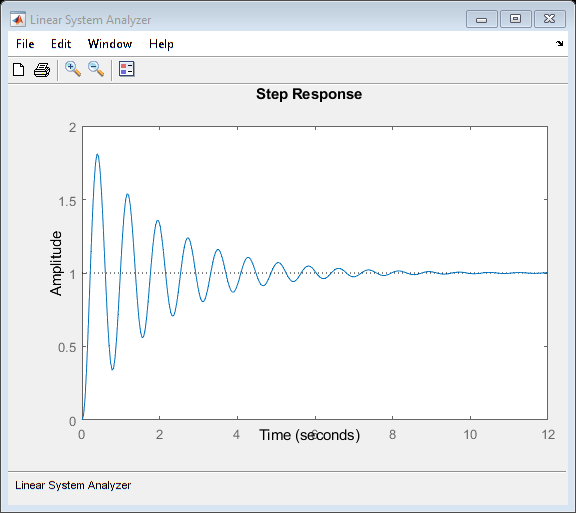

clc;
clear all;
clf;
s = tf('s');
G1 = 100/(s+100);
G2 = 0.2083/(s*(s+1.71));
K = 1000;
G = series(K*G1,G2);
H = 1/pi;
M = series(feedback(G,H),H);
ltiview(M);

## By replacing the power amplifier with a transfer function of unity

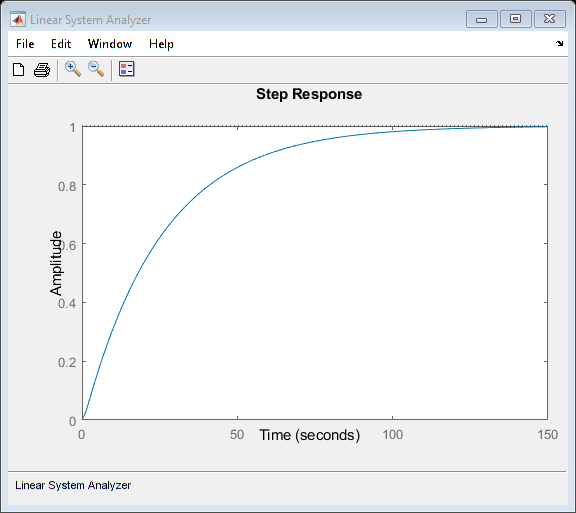

clc;
clear all;
clf;
s = tf('s');
G1 = 100/(s+100);
G2 = 0.2083/(s*(s+1.71));
K = 1;
G = series(K*G1,G2);
H = 1/pi;
M = series(feedback(G,H),H);
ltiview(M);

## Example 5.2

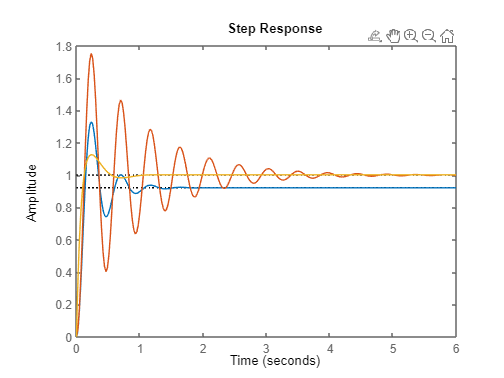

clc;
clear all;
clf;
s = tf('s');
G = 59.292/(s^2+6.9779*s+15.12);
D1 = 3;
D2 = 3 + 15/s;
D3 = 3 + 15/s +0.3*s;
M1 = feedback(D1*G,1);
M2 = feedback(D2*G,1);
M3 = feedback(D3*G,1);
step(M1);
hold on;
step(M2);
step(M3);

## Example 5.3

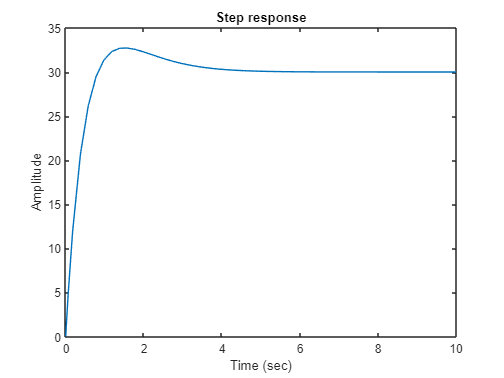

clc;
clear all;
clf;
open_system('Example_5_3.slx');
out = sim('Example_5_3.slx');
time = out.smout.Time;
data = out.smout.Data;
plot(time,data);
title('Step response');
xlabel('Time (sec)');
ylabel('Amplitude');

## Example 5.4

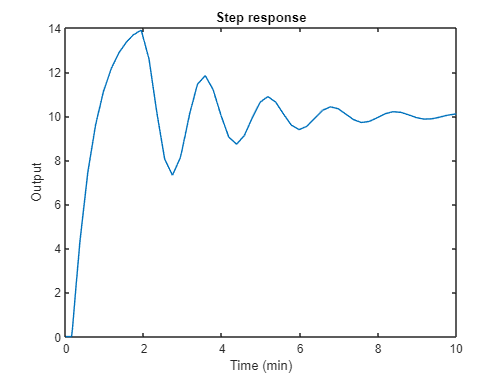

clclf;
open_system('Example_5_4.slx');
out = sim('Example_5_4.slx');
time = out.smout.Time;
data = out.smout.Data;
plot(time,data);
title('Step response');
xlabel('Time (min)');
ylabel('Output');

ymax = max(data);
step_size = 10;
peak_overshoot = ((ymax-step_size)/step_size)*100

peak_overshoot = 38.9991

index_peak = find(data == ymax);
peak_time = time(index_peak)

peak_time = 1.9338

s = length(time);
while((data(s)>=0.95*step_size) & (data(s)<=1.05*step_size))
s = s-1;
end
settling_time = time(s)

settling_time = 5.9737